#  创建环境

% 从预定义的环境直接创建 
env = rlPredefinedEnv("SimplePendulumWithImage-Continuous");

% 获取动作和状态规范
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

% 固定随机种子
rng(0)

# 创建智能体

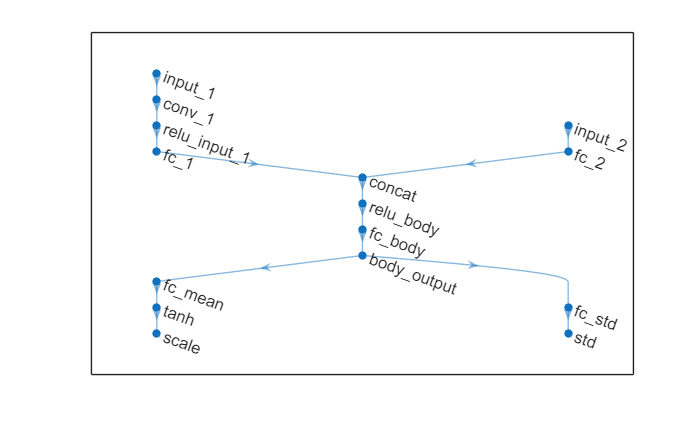

% 创建智能体的另外一种方式（即rlACAgent函数的另一种用法）

% 自动生成actor和critic
initOpts = rlAgentInitializationOptions(NumHiddenUnit=128);

% 设置AC超参数
agentoption = rlACAgentOptions(DiscountFactor=0.99, SampleTime=-1);

% 正式创建智能体
agent = rlACAgent(obsInfo, actInfo, initOpts, agentoption);

% 查看自动生成的actor网络和critic网络结构
actorNet = getModel(getActor(agent));
criticNet = getModel(getCritic(agent));
plot(layerGraph(actorNet))

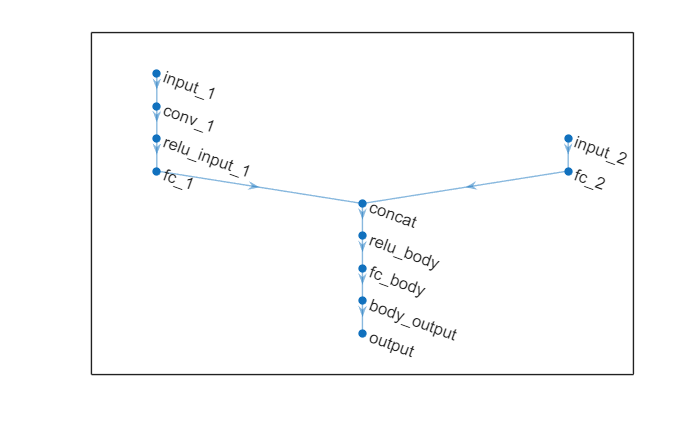

plot(layerGraph(criticNet))


% % （补充）利用原来的方式创建智能体
% actor1 = rlContinuousGaussianActor(getModel(getActor(agent)), obsInfo, actInfo, ActionMeanOutputNames='scale', ActionStandardDeviationOutputNames='std', ObservationInputNames=actorNet.InputNames);
% critic1 = rlValueFunction(getModel(getCritic(agent)), obsInfo, Observation=criticNet.InputNames);
% agent1 = rlACAgent(actor1, critic1, agentoption);

# 训练算法

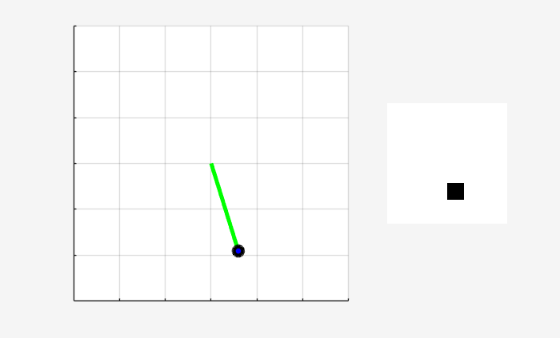

Episode:   1/200 | Episode reward: -8429.06 | Episode steps: 1000 | Average reward: -8429.06 | Step Count: 1000 | Episode Q0:     0.03
Episode:   2/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8535.59 | Step Count: 2000 | Episode Q0:  -368.42
Episode:   3/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8571.09 | Step Count: 3000 | Episode Q0: -1739.07
Episode:   4/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8588.85 | Step Count: 4000 | Episode Q0:  -773.11
Episode:   5/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8599.50 | Step Count: 5000 | Episode Q0:  -424.89
Episode:   6/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8642.11 | Step Count: 6000 | Episode Q0:  -326.05
Episode:   7/200 | Episode reward: -8642.11 | Episode steps: 1000 | Average reward: -8642.11 | Step Count: 7000 | Episode Q0:  -332.70
Episode:   8/200 | Episode reward: -8642.11 | Episode s

% 设置训练选项
trainOpts = rlTrainingOptions( ...
    "MaxEpisodes",200, ...
    "MaxStepsPerEpisode",1000, ...
    "StopTrainingCriteria","EpisodeReward", ...
    "StopTrainingValue",40, ...
    "SaveAgentCriteria","EpisodeReward", ...
    "SaveAgentValue",40, ...
    "Verbose",true, ...
    "Plots","none");

% 可视化倒立摆环境
plot(env)

% 正式开始训练智能体
trainingStats = train(agent,env,trainOpts);

# 使用训练好的智能体与环境交互

plot(env)

% 设置仿真选项
simoptions = rlSimulationOptions(MaxSteps=500);

% 训练好的智能体与环境进行交互
sim(env,agent,simoptions)